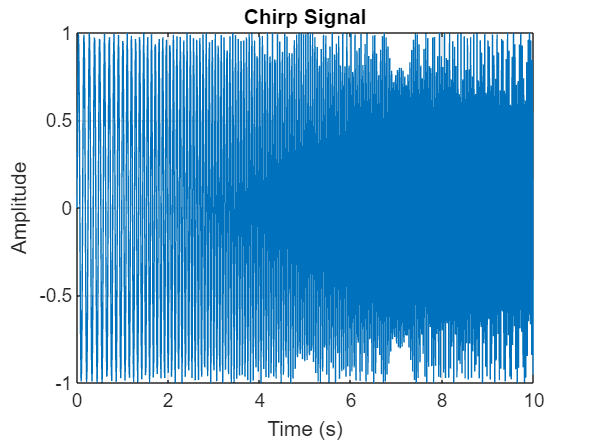

alpha = 1 + mod(230,3);
Fs = 100;    % Sampling rate (samples per second)
duration = 10; % Duration of the signal in seconds
t = 0:1/Fs:duration-1/Fs; % Time vector
% Define the instantaneous frequency function F(t)
initial_freq = 2 + 2*alpha;
final_freq = 5 + 5*alpha;
F_t = linspace(initial_freq, final_freq, length(t));
% Generate the chirp signal
x = sin(2*pi*F_t.*t);
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Chirp Signal');
grid on;

Problem 1.2

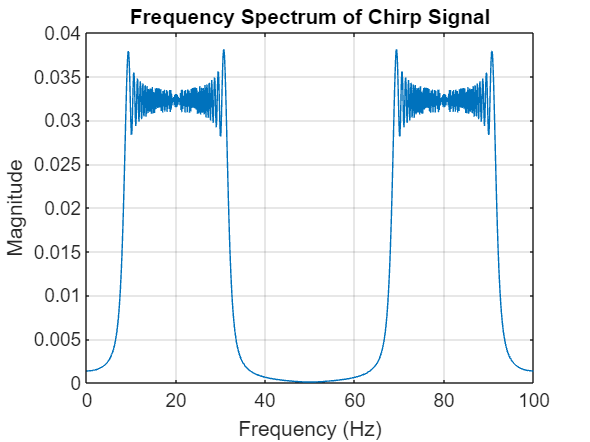

% Calculate the FFT of the signal
N = length(x); % Length of the signal
X = fft(x);
frequencies = (0:N-1) * (Fs/N); % Frequency axis
X_magnitude = abs(X) / N;
figure;
plot(frequencies, X_magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum of Chirp Signal');
grid on;

[max_magnitude, max_index] = max(X_magnitude);
dominant_frequency = frequencies(max_index);
fprintf('Dominant Frequency Component: %.2f Hz\n', dominant_frequency);

Dominant Frequency Component: 30.70 Hz


Problem 1.3(a)

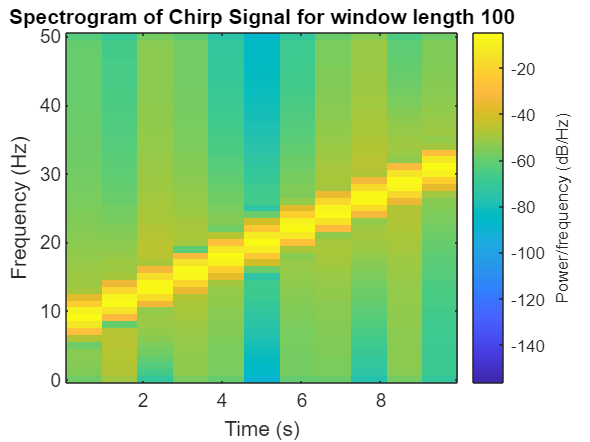

window_length = 100; % Hamming window length in samples
overlap = 10; % Overlap in samples
figure;
spectrogram(x, hamming(window_length), overlap, window_length, Fs, 'yaxis');
title('Spectrogram of Chirp Signal for window length 100');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

Problem 1.3(b)

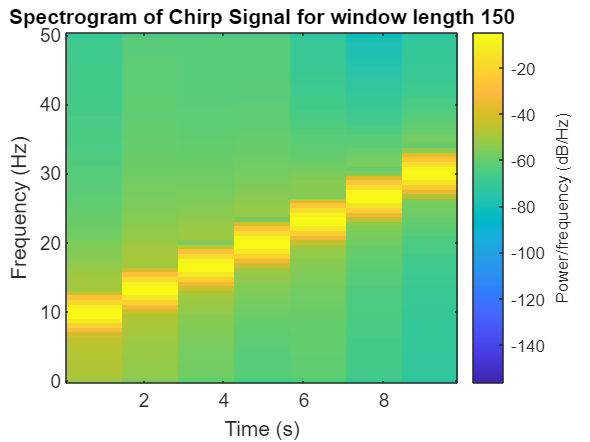

window_length = 150; % Hamming window length in samples
overlap = 10; % Overlap in samples
figure;
spectrogram(x, hamming(window_length), overlap, window_length, Fs, 'yaxis');
title('Spectrogram of Chirp Signal for window length 150');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

Problem 1.3©

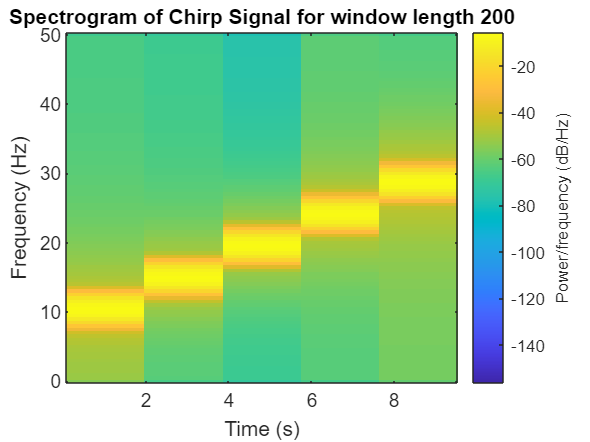

window_length = 200; % Hamming window length in samples
overlap = 10; % Overlap in samples
figure;
spectrogram(x, hamming(window_length), overlap, window_length, Fs, 'yaxis');
title('Spectrogram of Chirp Signal for window length 200');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

Problem 2.1

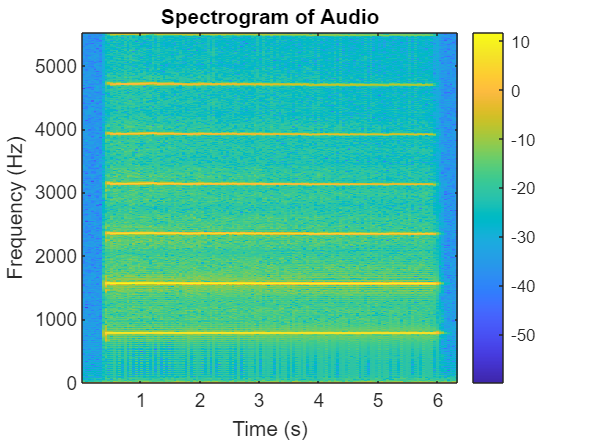

filename = 'instru3.wav';
[x, Fs] = audioread(filename);
window_size = 1024; % You can adjust the window size as needed
overlap = 512; % Overlap between consecutive windows
nfft = 2048; % FFT size for spectrogram
[S, f, t] = spectrogram(x, hamming(window_size), overlap, nfft, Fs);
magnitude_spectrum = abs(S);
[~, max_freq_indices] = max(magnitude_spectrum);
fundamental_frequencies = f(max_freq_indices);
figure;
imagesc(t, f, 10*log10(magnitude_spectrum));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Audio');
colorbar;

fprintf('Fundamental Pitch (from spectrogram):\n');

Fundamental Pitch (from spectrogram):


fprintf('Time (s)   Fundamental Frequency (Hz)\n');

Time (s)   Fundamental Frequency (Hz)


for i = 1:length(t)
    fprintf('%.2f        %.2f\n', t(i), fundamental_frequencies(i));
end

0.05        0.00
0.09        0.00
0.14        0.00
0.19        0.00
0.23        0.00
0.28        0.00
0.33        0.00
0.37        0.00
0.42        1571.92
0.46        1571.92
0.51        1571.92
0.56        1566.54
0.60        1571.92
0.65        1571.92
0.70        1571.92
0.74        1571.92
0.79        1571.92
0.84        1571.92
0.88        1571.92
0.93        1571.92
0.98        1571.92
1.02        1571.92
1.07        1571.92
1.11        1571.92
1.16        1571.92
1.21        1571.92
1.25        1571.92
1.30        1571.92
1.35        1571.92
1.39        1571.92
1.44        1571.92
1.49        1571.92
1.53        1571.92
1.58        1571.92
1.63        1571.92
1.67        1571.92
1.72        1566.54
1.76        1566.54
1.81        1566.54
1.86        1566.54
1.90        1571.92
1.95        1566.54
2.00        1571.92
2.04        1571.92
2.09        1571.92
2.14        1571.92
2.18        1571.92
2.23        1566.54
2.28        1571.92
2.32        1571.92
2.37        1571.92
2.41

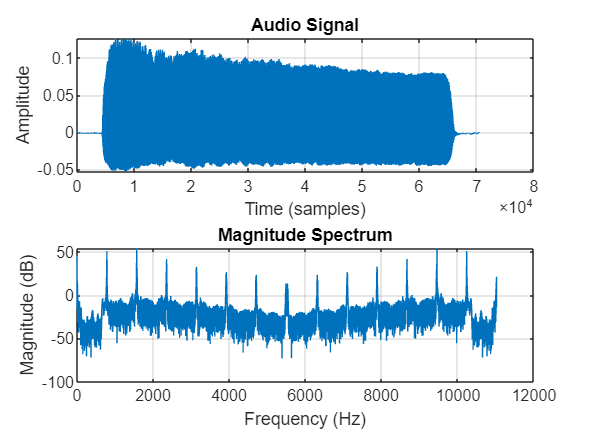

figure;
subplot(2, 1, 1);
plot(x);
xlabel('Time (samples)');
ylabel('Amplitude');
title('Audio Signal');
grid on;

subplot(2, 1, 2);
N = length(x);
frequencies = (0:N-1) * (Fs/N);
spectrum = abs(fft(x, N));
plot(frequencies, 20*log10(spectrum));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum');
grid on;

[~, max_freq_index] = max(spectrum);
fundamental_frequency = frequencies(max_freq_index);

fprintf('\nFundamental Pitch (from spectrum):\n');


Fundamental Pitch (from spectrum):


fprintf('Fundamental Frequency (Hz): %.2f\n', fundamental_frequency);

Fundamental Frequency (Hz): 1566.24


Problem 2.2 

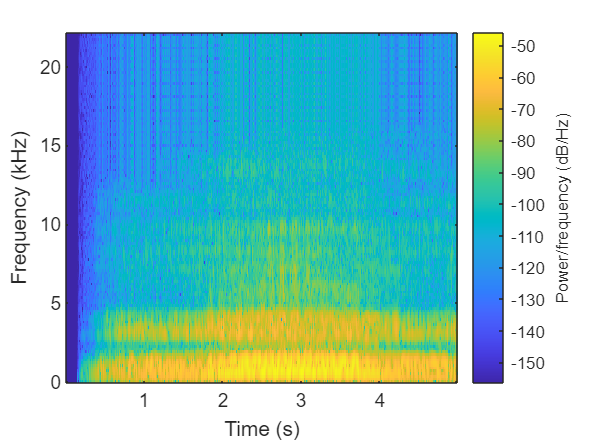

[y, Fs] = audioread('Opera.wav');
%c
% Calculate the spectrogram
 figure;
 spectrogram(y, hamming(100), 10, [], Fs, 'yaxis');

% title('Spectrogram of Opera.wav');
% xlabel('Time (seconds)');
% ylabel('Frequency (Hz)');
% colorbar;

Problem 3

% Create an audio recorder object
recObj = audiorecorder(4000, 16, 1); % Sampling rate: 4000 Hz, 16-bit depth, mono
disp('Recording...');

Recording...


recordblocking(recObj, 5); % Adjust the duration as needed
disp('Recording complete.');

Recording complete.


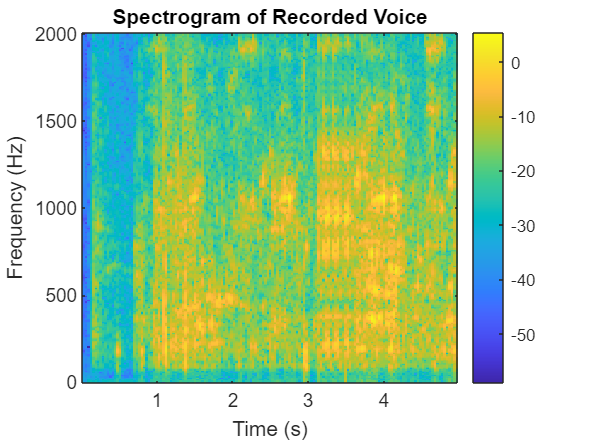

% Save the recorded audio to a .wav file
filename = 'my_voice.wav';
audiowrite(filename, getaudiodata(recObj), recObj.SampleRate);
% Load the recorded audio file
filename = 'my_voice.wav';
[x, Fs] = audioread(filename);
% Calculate the spectrogram
window_size = 256; % You can adjust the window size as needed
overlap = 128; % Overlap between consecutive windows
nfft = 512; % FFT size for spectrogram
[S, f, t] = spectrogram(x, hamming(window_size), overlap, nfft, Fs);
% Plot the spectrogram
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Recorded Voice');
colorbar;